# EA 999 : Designing Audio Filter for FPGA Implementation

Example for Low Pass Filter w/ fcut = 200Hz. Further specifications are given below. 

## Observations:

        - Selected as filter type:  linear phase equiripple FIR 

        - The filter design was done with  ***filterDesigner*** tool from Toolbox signal

        - Open: check the effect of the density factor

% Starting with a clean workspace
clear all, close all, clc

% All frequency values are in Hz.
Fs = 48000;  % Sampling Frequency

N     = 254;  % Order
Fpass = 200;  % Passband Frequency   % 1k6/ 800/400/200/
Fstop = 400;  % Stopband Frequency   % 1k8/1000/600/400/
Wpass = 1;    % Passband Weight      %  2 / 2 /  2 / 1 /
Wstop = 1;    % Stopband Weight      %  1 /  1 / 1 / 1 /

% Calculate the coefficients using the FIRLS function.
b  = firls(N, [0 Fpass Fstop Fs/2]/(Fs/2), [1 1 0 0], [Wpass Wstop]);

n = 0:1:length(b)-1;
figure()
plot(n,b), grid on, title('Taps from LPF FIRLS Method'), hold

Current plot held


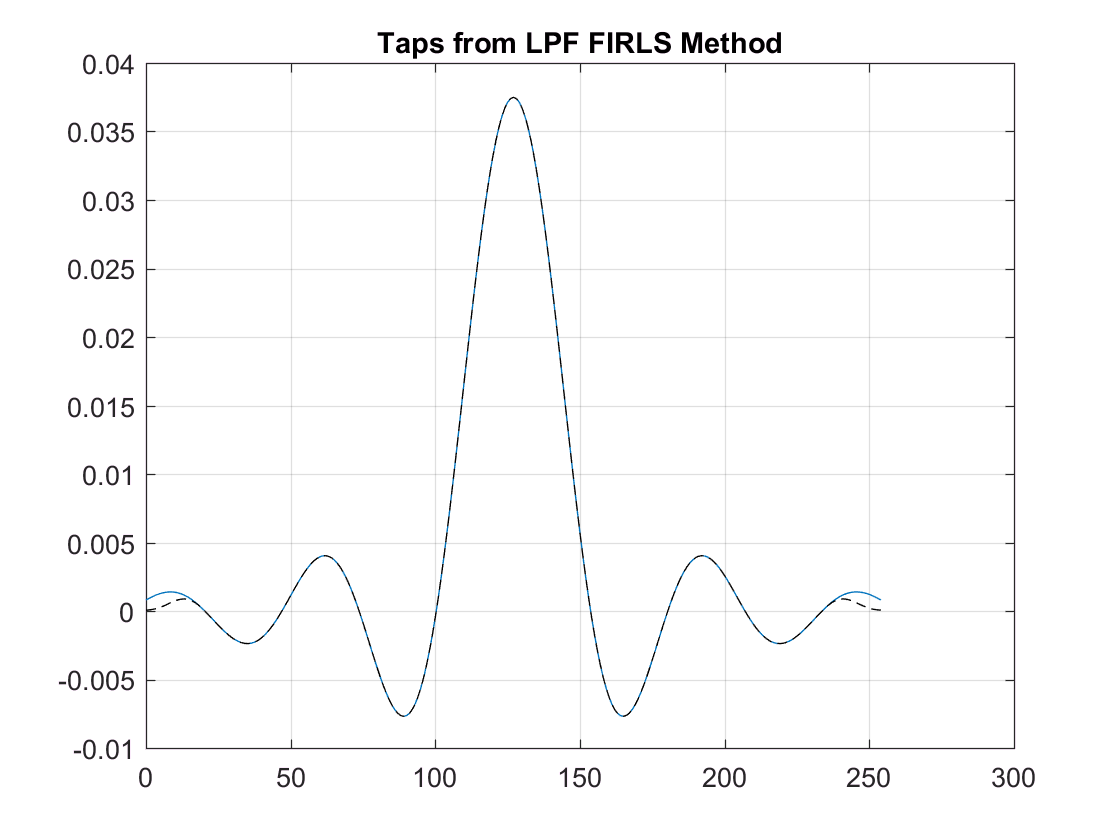


% Smoothing Fade-In/Out (avoid pfiffing)
M = 20;
%aux = ones(1,M)-cos([0:pi/(2*M):(M-1)*pi/(2*M)]);
%wdw = [aux(1:end),ones(1,(N+1-2*M)),aux(end:-1:1)];
aux = hamming(2*M+1)';
wdw = [aux(1:M),ones(1,(N+1-2*M)),aux(M+2:end)];
b = b.*wdw;
plot(n,b,'k--')

## Quantisation of the Filter Coefficients

Next step is to quantisise the filter coefficients with a fix number of bits, using 2-complement notation for the signed values of the coefficients.

In order to have an idea of the required definition for the coefficients, check the relationship between the max and min absolute values:

display('Relationship between max and min filter coefficients:') 

Relationship between max and min filter coefficients:


max_o_min = max(abs(b))/min(abs(b))

max_o_min = 5.0400e+03

display('and in number of bits:')

and in number of bits:


N_quant_min= log2(max_o_min)

N_quant_min = 12.2992

So if possible take 9-10 bits for absolute values and 1 for sign. 

=====================================================================

**OBS**.: after changing the filter specification as we discussed this morning could reduce the Nres.

But right now will not change that (keep Nres=12), cause:

- FPGA mem-block width is either 16 or 32, and using audio samples with 16bits

- So can keep coefficients with Nres = (32 - 16 - margin) ) 

- Plus, need to check influence for audio_quality, and reasonable values to implement BPFs with similar BWs

We can change later if we see needs/advantages.

=====================================================================

Will try out below a quantisation using 12-bits for signed values and check error magnitude, and resulting frequency response. 

Currently the b coefficients are scaled to give         $ \sum__{n=0} ^^{n=255} \quad {b[n]} \approx 1

$

display('Sum of all coefficients, to check current scaling factor:')

Sum of all coefficients, to check current scaling factor:


sum_b = sum(b)

sum_b = 0.9900

The ideal scaling factor is the one which maximises the usage of the quantisation range: 


$$[ -2^{11} \enspace;\enspace  +(2^{11})-1 ] 
= 
[-2048 \enspace;\enspace +2047 ]$$


N_quant = 12;
display('Ideal scaling factor to fully use quantisation range:')

Ideal scaling factor to fully use quantisation range:


scale_factor = (2^(N_quant-1)-1)/max(abs(b))

scale_factor = 5.4599e+04


b_scaled = b*scale_factor ; 

Now proceeding for quantisation and checks:


% Setting Resolution for coefficients, do not forget 1-bit is for sign
Nres_A = 6             % for comparison purposes

Nres_A = 6

Ndiff_A = N_quant - Nres_A ;

Nres_B = 12

Nres_B = 12

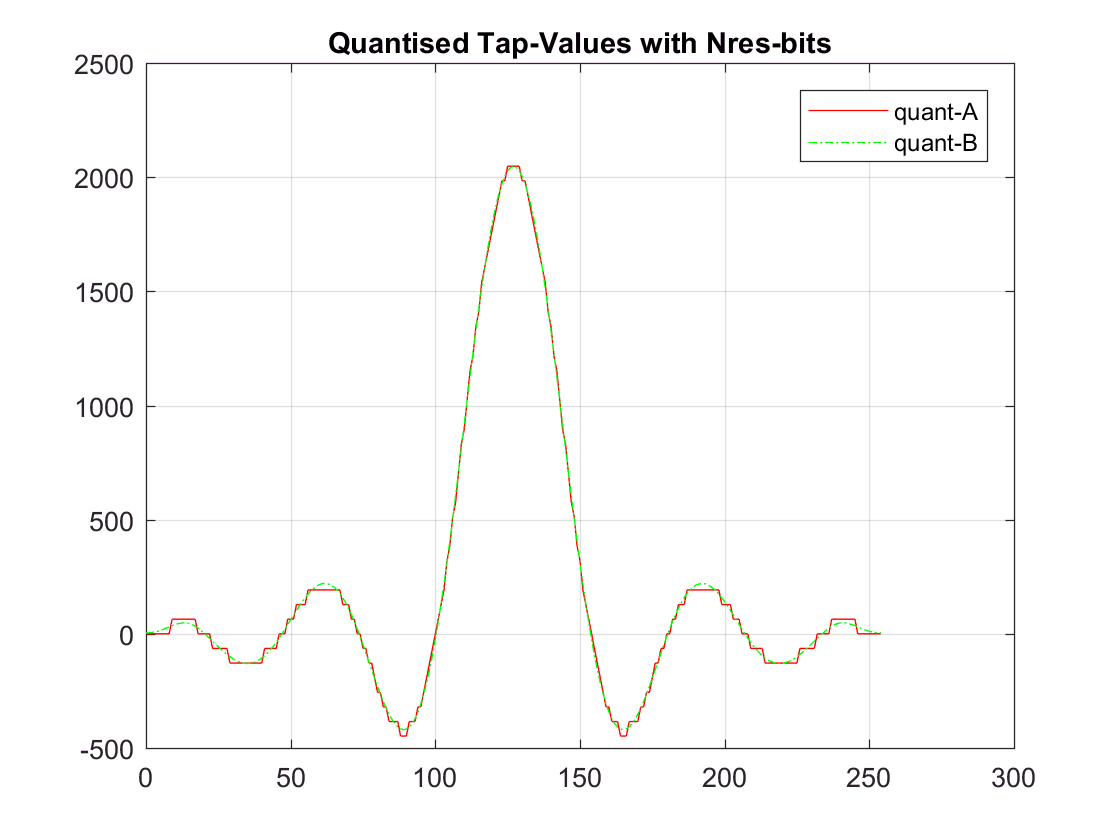

Ndiff_B = N_quant - Nres_B ;

% reducing resolution to Nres bits
b_quant_A = round (b_scaled / (2^Ndiff_A) ) *  2^Ndiff_A ;
b_quant_B = round (b_scaled / (2^Ndiff_B) ) *  2^Ndiff_B ;

figure(),plot(n,b_quant_A,'r',n,b_quant_B,'g-.'),grid on, 
title('Quantised Tap-Values with Nres-bits')
legend({'quant-A','quant-B'})

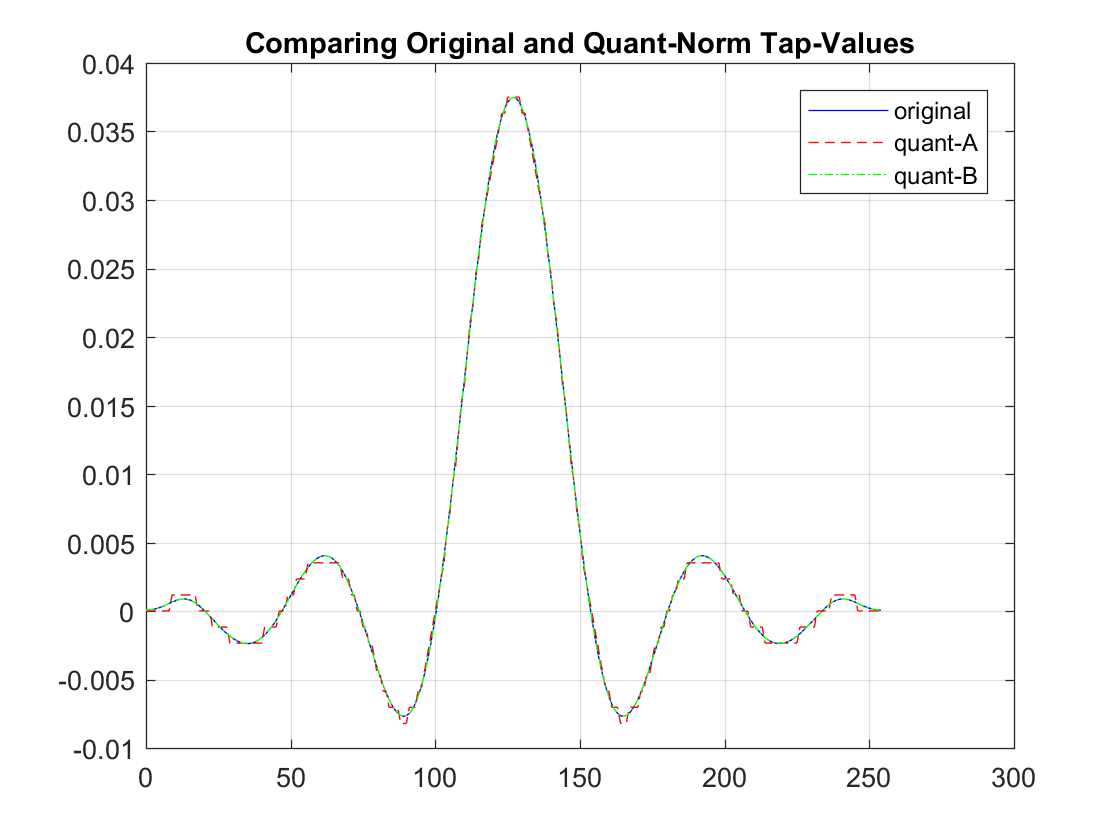


b_quant_A_norm = b_quant_A / scale_factor ;
b_quant_B_norm = b_quant_B / scale_factor ;

figure()
plot(n,b,'b',...
     n,b_quant_A_norm,'r--',...
     n,b_quant_B_norm,'g-.'), grid on,
title('Comparing Original and Quant-Norm Tap-Values')
legend({'original','quant-A','quant-B'})


display('Zooming in:')

Zooming in:


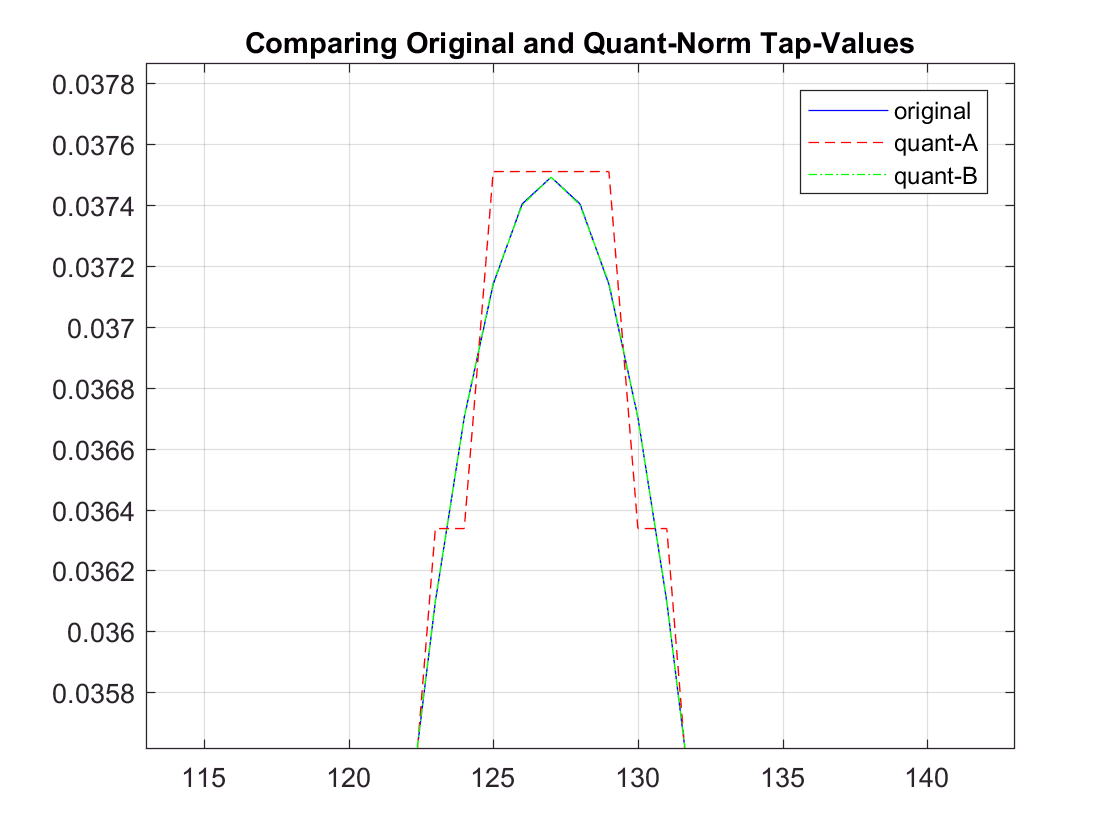

figure()
plot(n,b,'b',...
     n,b_quant_A_norm,'r--',...
     n,b_quant_B_norm,'g-.'), grid on,
title('Comparing Original and Quant-Norm Tap-Values')
legend({'original','quant-A','quant-B'})
axis([113 143 b(128)*0.95 b(128)*1.01 ])


% checking the norm of the filter (to check if 4-bit margin is enough
L1_norm = sum(abs(b_quant_B))        % absolute maximum (usually never achieved)
L2_norm = sqrt(sum(b_quant_B.^2))    % practical norm (usually to optimise SNR)
% 
% Since the margin we have 16-12=4bits, is well below the log2(L2_norm)
% it would be recommendable to add overflow control logic (clipping/saturation)

## Check Error in Time and Frequency Domains

Checking for the percentage error and changes in frequency domain:

display('Error relative to coeff-mean-value in %:')

Error relative to coeff-mean-value in %:


error_p_A = abs(b_quant_A_norm - b) / mean(abs(b)) * 100 ;
error_p_B = abs(b_quant_B_norm - b) / mean(abs(b)) * 100 ;

display('Maximum percentage error (with 2 values of Nres):')

Maximum percentage error (with 2 values of Nres):


max(error_p_A)

ans = 8.8819

max(error_p_B)

ans = 0.1394

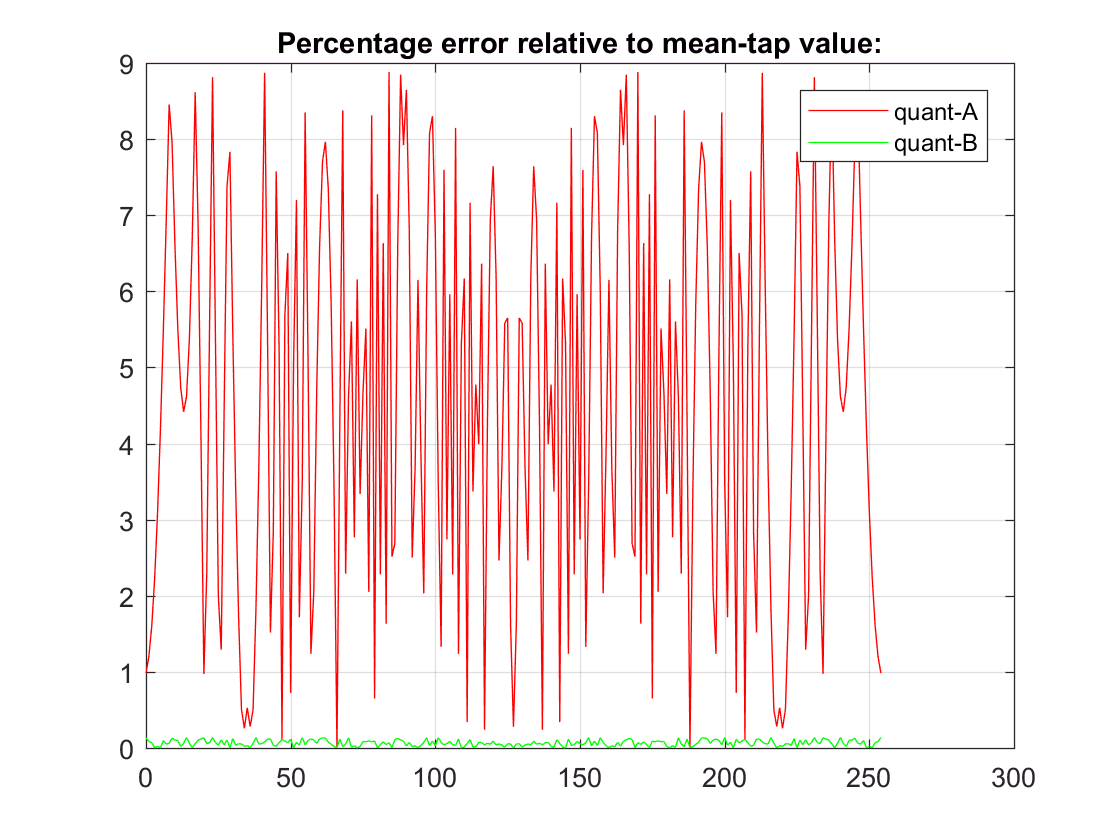


figure()
plot(n,error_p_A,'r',n,error_p_B,'g'),grid on, 
title('Percentage error relative to mean-tap value:')
legend({'quant-A','quant-B'})

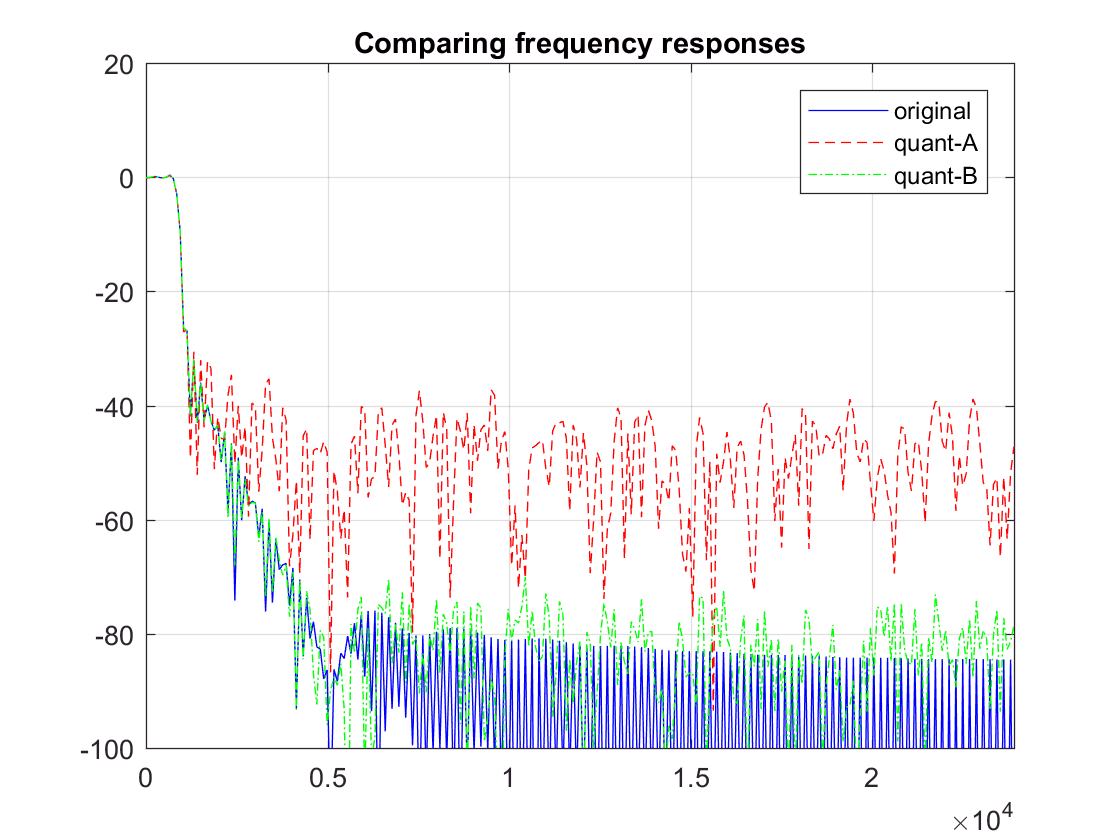


Fstep = Fs/2/(N+1);        % re-using N defined above (which is 255 and not 256!)
f = Fstep * [0:1:N]; 
H_f_b = freqz(b,[1],f,Fs);
H_f_bAq = freqz(b_quant_A_norm,[1],f,Fs);
H_f_bBq = freqz(b_quant_B_norm,[1],f,Fs);

figure()
plot(f,db(H_f_b),'b',...
     f,db(H_f_bAq),'r--',...
     f,db(H_f_bBq),'g-.'), grid on
title('Comparing frequency responses')
legend({'original','quant-A','quant-B'})
axis([0 f(end) -100 +20])


display('Zooming in:')

Zooming in:


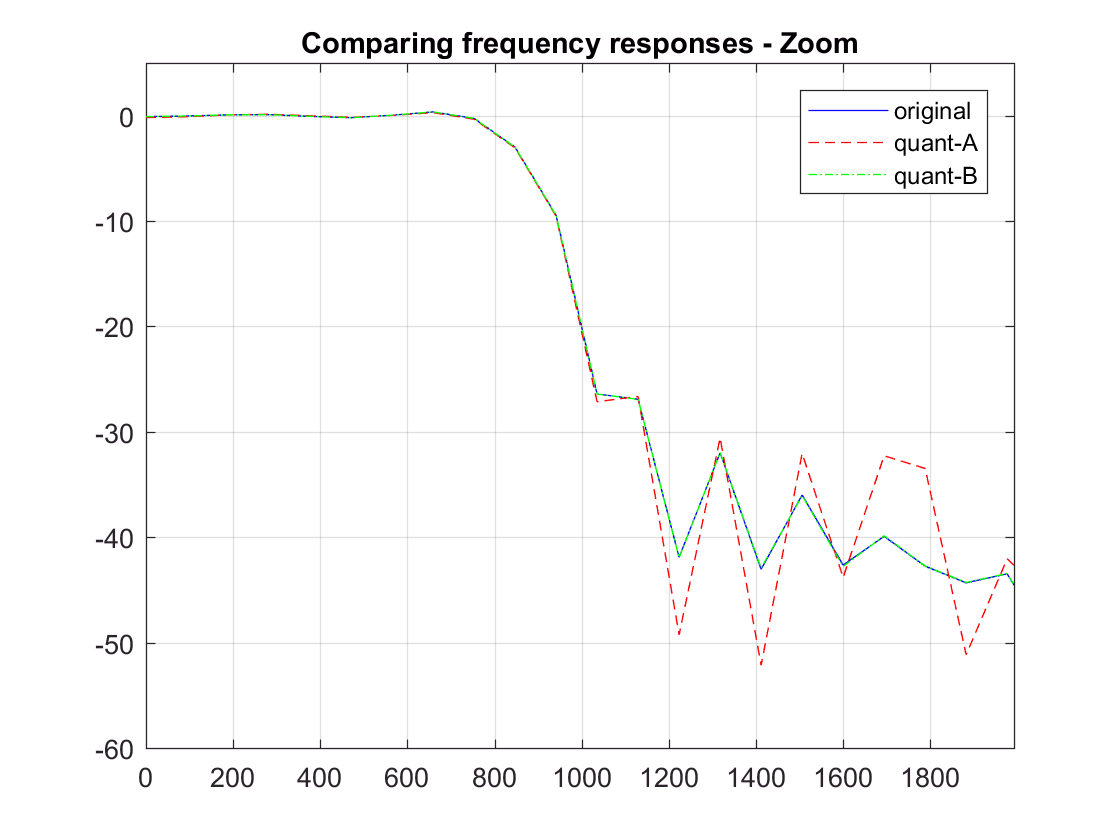

plot(f,db(H_f_b),'b',...
     f,db(H_f_bAq),'r--',...
     f,db(H_f_bBq),'g-.'), grid on
title('Comparing frequency responses - Zoom')
axis([0 f(end)/12 -60 +5])
legend({'original','quant-A','quant-B'})

## Exporting Coefficients for FPGA Implementation

`Before exporting, checking coefficient range utilisation: `

display('Checking if LSB is used')

Checking if LSB is used


find(mod(b_quant_B,2))

ans =      5     6     8    13    16    18    19    20    21    25    26    27    31    35    37    39    40    43    44    46    47    50    51    59    60    65    68    71    76    78    86    91    93    94    97    98    99   103   104   106   108   110   112   115   117   118   119   120   121   123



display('Checking if MSB is used')

Checking if MSB is used


find(double(b_quant_B > 2^(Nres_B-2)))

ans =    113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143



display('Export and echo exported csv-list')

Export and echo exported csv-list


csvwrite('csvlist_coeffs_lpf_200Hz.dat',b_quant_B) 
% csvwrite('csvlist_coeffs_lpf_1k6Hz.dat',b_quant_B) % /400/800/1k6
type csvlist_coeffs_lpf_200Hz.dat


4,4,6,8,11,15,20,25,30,36,40,44,47,48,48,45,40,33,25,15,3,-8,-20,-32,-45,-57,-69,-80,-90,-100,-109,-116,-122,-126,-129,-130,-129,-126,-121,-115,-106,-96,-83,-69,-54,-37,-19,0,20,41,61,82,102,122,140,158,174,188,199,209,216,220,220,218,213,204,192,177,158,136,111,84,54,22,-12,-47,-84,-121,-158,-194,-230,-264,-296,-326,-352,-375,-394,-408,-416,-420,-417,-408,-393,-371,-342,-306,-263,-213,-157,-94,-24,52,133,219,310,405,504,605,708,813,918,1023,1126,1228,1327,1422,1513,1599,1679,1753,1819,1878,1929,1971,2004,2028,2042,2047,2042,2028,2004,1971,1929,1878,1819,1753,1679,1599,1513,1422,1327,1228,1126,1023,918,813,708,605,504,405,310,219,133,52,-24,-94,-157,-213,-263,-306,-342,-371,-393,-408,-417,-420,-416,-408,-394,-375,-352,-326,-296,-264,-230,-194,-158,-121,-84,-47,-12,22,54,84,111,136,158,177,192,204,213,218,220,220,216,209,199,188,174,158,140,122,102,82,61,41,20,0,-19,-37,-54,-69,-83,-96,-106,-115,-121,-126,-129,-130,-129,-126,-122,-116,-109,-100,-90,-80,-69,-57,-45,-32,-20,-8,3,15,25,33

Export z^(-127) for delayed input used in complementary filter

% dled_in = zeros(1,255);
% dled_in(128) = (2^15)-1
% 
% figure;
% plot(dled_in)
% 
% display('Export and echo exported csv-list')
% csvwrite('csvlist_coeffs_dled_in.dat',dled_in) 
% type csvlist_coeffs_dled_in.dat